**Analyse descristipe et statistique des données cas par cas**

%% Comparaison des données qualitatives et quantitatives des patients Controlatérale vs PréOP %%

%% 1. Extraction des données
% Extraction des colonnes 
HT_Max_Asympto = KINcontrolvspre(:,2);
HT_Range_Asympto = KINcontrolvspre(:,3);
HT_Max_Pre = KINcontrolvspre(:,5);
HT_Range_Pre = KINcontrolvspre(:,6);

% Calcul des deltas (différences)
Delta_Max = HT_Max_Pre - HT_Max_Asympto;
Delta_Range = HT_Range_Pre - HT_Range_Asympto;

% Création d'une matrice des paires pour faciliter l'analyse
data_Asympto = [HT_Max_Asympto, HT_Range_Asympto];
data_Pre = [HT_Max_Pre, HT_Range_Pre];
delta_data = [Delta_Max, Delta_Range];
var_names = {'HT Max', 'HT Range'};

%% 2. Analyse descriptive
% Création d'une table de statistiques descriptives
fprintf('=== Statistiques descriptives ===\n\n');

=== Statistiques descriptives ===



for i = 1:2
    fprintf('--- %s ---\n', var_names{i});
    fprintf('Asymptomatique  : Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n', ...
        mean(data_Asympto(:,i)), std(data_Asympto(:,i)), median(data_Asympto(:,i)));
    fprintf('Pre-opératoire : Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n', ...
        mean(data_Pre(:,i), 'omitnan'), std(data_Pre(:,i), 'omitnan'), median(data_Pre(:,i), 'omitnan'));
    fprintf('Delta : Moyenne = %.2f, Écart-type = %.2f, Médiane = %.2f\n\n', ...
        mean(delta_data(:,i)), std(delta_data(:,i)), median(delta_data(:,i)));
end

--- HT Max ---


Asymptomatique  : Moyenne = 64.70, Écart-type = 10.15, Médiane = 66.50


Pre-opératoire : Moyenne = 35.50, Écart-type = 18.38, Médiane = 29.00


Delta : Moyenne = -29.20, Écart-type = 20.13, Médiane = -31.00



--- HT Range ---


Asymptomatique  : Moyenne = 47.75, Écart-type = 7.55, Médiane = 48.50


Pre-opératoire : Moyenne = 25.05, Écart-type = 14.71, Médiane = 18.50


Delta : Moyenne = -22.70, Écart-type = 15.83, Médiane = -24.00




%% 3. Test de normalité des différences (requis pour test t apparié)
fprintf('=== Tests de normalité (Shapiro-Wilk) sur les deltas ===\n');

=== Tests de normalité (Shapiro-Wilk) sur les deltas ===


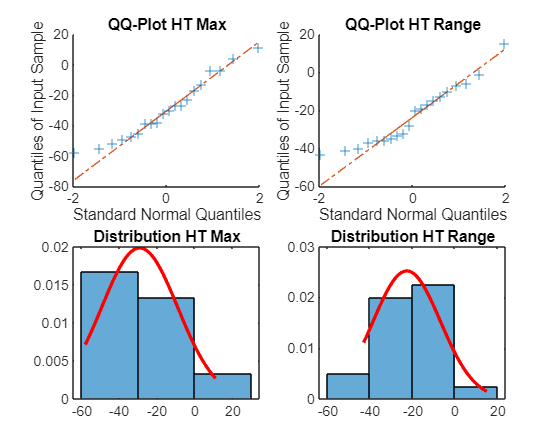

 - HT Max : p = 0.5000, Distribution suit une loi normale
 - HT Range : p = 0.1215, Distribution suit une loi normale


figure('Name', 'Test de normalité des différences', 'Position', [100,100,1000,800]);
for i = 1:2
    % QQ-Plot pour visualiser la normalité
    subplot(2,2,i);
    qqplot(delta_data(:,i));
    title(['QQ-Plot ' var_names{i}]);
    
    % Histogramme avec courbe de densité normale
    subplot(2,2,i+2);
    histogram(delta_data(:,i), 'Normalization', 'pdf');
    hold on;
    x = linspace(min(delta_data(:,i)), max(delta_data(:,i)), 100);
    mu = mean(delta_data(:,i));
    sigma = std(delta_data(:,i));
    y = normpdf(x, mu, sigma);
    plot(x, y, 'r-', 'LineWidth', 2);
    title(['Distribution ' var_names{i}]);
    hold off;
    
    % Test de Shapiro-Wilk pour la normalité
    [H, pValue] = swtest(delta_data(:,i), 0.05);
    normalite = ~H; % H=0 signifie que l'hypothèse de normalité n'est pas rejetée
    
    fprintf(' - %s : p = %.4f, Distribution %s normale\n', ...
        var_names{i}, pValue, conditional(normalite, 'suit une loi', 'ne suit PAS une loi'));
end

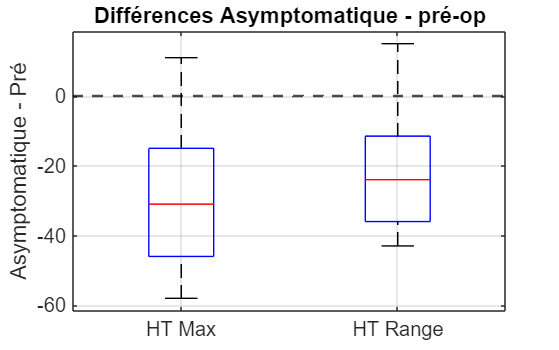

fprintf('\n');

%% 4. Visualisations des données
% Boxplots des deltas
figure('Name', 'Comparaisons Asymptomatique/Pré (Delta)', 'Position', [100,100,800,500]);
boxplot(delta_data, 'Labels', var_names);
ylabel('Asymptomatique - Pré');
title('Différences Asymptomatique - pré-op');
ax = gca; ax.FontSize = 12;
hold on; 
yline(0, '--k', 'LineWidth', 1.5);
grid on;

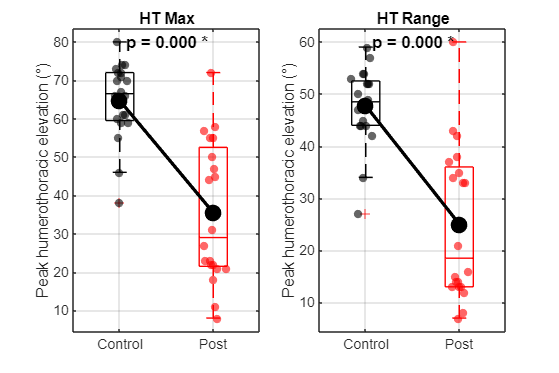


% Lignes sujet par sujet avec boxplot combinés
figure('Name', 'Asymptomatique vs Pré avec Boxplots et Points', 'Position', [100,100,1200,800]);
for i = 1:2
    subplot(1,2,i); 

    set(gcf, 'Color', 'white');
    
    % Boxplots
    boxplot([data_Asympto(:,i); data_Pre(:,i)], ...
        [repmat({'Asymptomatique'}, length(data_Asympto), 1); repmat({'Pré'}, length(data_Pre), 1)], ...
        'Colors', 'kr');
    hold on;
    
    % Points individuels
    scatter(repmat(1, length(data_Asympto), 1) + randn(length(data_Asympto),1)*0.05, data_Asympto(:,i), 25, 'k', 'filled', 'MarkerFaceAlpha', 0.6);
    scatter(repmat(2, length(data_Pre), 1) + randn(length(data_Pre),1)*0.05, data_Pre(:,i), 25, 'r', 'filled', 'MarkerFaceAlpha', 0.6);
    
    % Moyennes
    plot([1,2], [mean(data_Asympto(:,i)), mean(data_Pre(:,i), 'omitnan')], '-o', 'Color', 'k', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    
    title(var_names{i}); 
    xticks([1 2]); 
    xticklabels({'Control', 'Post'});
    ylabel('Peak humerothoracic elevation (°)');
    grid on;

    % Ajout de la valeur p à chaque graphique
    [~, p_value] = ttest(data_Asympto(:,i), data_Pre(:,i));
    if p_value < 0.05
        significance = ' *';
    elseif p_value < 0.01
        significance = ' **';
    elseif p_value < 0.001
        significance = ' ***';
    else
        significance = ' (ns)';
    end
    
    text(1.5, max([data_Asympto(:,i); data_Pre(:,i)]), ['p = ' num2str(p_value, '%.3f') significance], ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    
    hold off;
end


%% 5. Tests statistiques
fprintf('=== Tests statistiques (Asymptomatique vs Pré) ===\n\n');

=== Tests statistiques (Asymptomatique vs Pré) ===




% Pour chaque variable, choisir le test approprié selon la normalité
for i = 1:2
    [H_sw, p_sw] = swtest(delta_data(:,i), 0.05);
    normalite = ~H_sw;
    
    if normalite
        % Test t apparié si les différences suivent une loi normale
        [h, p_value, ci, stats] = ttest2(data_Asympto(:,i), data_Pre(:,i));
        test_type = 'Test t indépendant';
        t_val = stats.tstat;
        df = stats.df;
        test_stat = sprintf('t(%d) = %.2f', df, t_val);
    else
        % Test non paramétrique si non-normalité
        [p_value, h, stats] = ranksum(data_Asympto(:,i), data_Pre(:,i));
        test_type = 'Test de Mann Whitney';
        test_stat = sprintf('Z = %.2f', stats.zval);
    end
    
    % Taille d'effet
    cohen_d = (mean(data_Pre(:,i)) - mean(data_Asympto(:,i))) / ...
              std(delta_data(:,i));
    
    % Rapport des résultats
    fprintf('--- %s ---\n', var_names{i});
    fprintf('Test utilisé: %s (normalité: p = %.4f)\n', test_type, p_sw);
    fprintf('Asymptomatique: M = %.2f, ET = %.2f; Pré-opératoire: M = %.2f, ET = %.2f\n', ...
        mean(data_Asympto(:,i)), std(data_Asympto(:,i)), ...
        mean(data_Pre(:,i)), std(data_Pre(:,i)));
    fprintf('Résultat: %s, p = %.4f', test_stat, p_value);
    
    % Interprétation
    if p_value < 0.05
        fprintf(' (significatif)\n');
        direction = conditional(mean(delta_data(:,i)) > 0, 'augmentation', 'diminution');
        fprintf('Interprétation: %s significative entre Asymptomatique et Pre-opératoire\n', direction);
    else
        fprintf(' (non significatif)\n');
        fprintf('Interprétation: Pas de différence significative entre Asymptomatique et Pre-opératoire\n');
    end
    
    fprintf('Taille d''effet: d de Cohen = %.2f (%s)\n\n', cohen_d, interAsymptotCohenD(cohen_d));
end

--- HT Max ---


Test utilisé: Test t indépendant (normalité: p = 0.5000)


Asymptomatique: M = 64.70, ET = 10.15; Pré-opératoire: M = 35.50, ET = 18.38


Résultat: t(38) = 6.22, p = 0.0000

 (significatif)


Interprétation: diminution significative entre Asymptomatique et Pre-opératoire


Taille d'effet: d de Cohen = -1.45 (effet fort)



--- HT Range ---


Test utilisé: Test t indépendant (normalité: p = 0.1215)


Asymptomatique: M = 47.75, ET = 7.55; Pré-opératoire: M = 25.05, ET = 14.71


Résultat: t(38) = 6.14, p = 0.0000

 (significatif)


Interprétation: diminution significative entre Asymptomatique et Pre-opératoire


Taille d'effet: d de Cohen = -1.43 (effet fort)




%% 6. Tableau récapitulatif pour publication
% Création d'une table organisée pour rapporter les résultats
results_table = table;
results_table.Variable = var_names';
results_table.Asympto_Mean = mean(data_Asympto)';
results_table.Asympto_SD = std(data_Asympto)';
results_table.Pre_Mean = mean(data_Pre)';
results_table.Pre_SD = std(data_Pre)';
results_table.Delta_Mean = mean(delta_data)';
results_table.Delta_SD = std(delta_data)';
results_table.P_Value = zeros(2,1);
results_table.Effect_Size = zeros(2,1);

for i = 1:2
    [~, p] = ttest(data_Asympto(:,i), data_Pre(:,i));
    results_table.P_Value(i) = p;
    results_table.Effect_Size(i) = (mean(data_Pre(:,i)) - mean(data_Asympto(:,i))) / std(delta_data(:,i));
end

% Affichage du tableau récapitulatif
disp('=== Tableau récapitulatif pour publication ===');

=== Tableau récapitulatif pour publication ===


disp(results_table);

      Variable      Asympto_Mean    Asympto_SD    Pre_Mean    Pre_SD    Delta_Mean    Delta_SD     P_Value      Effect_Size
    ____________    ____________    __________    ________    ______    __________    ________    __________    ___________

    {'HT Max'  }        64.7          10.152        35.5       18.38      -29.2         20.13     3.2417e-06      -1.4506  
    {'HT Range'}       47.75          7.5455       25.05      14.713      -22.7        15.832     3.7832e-06      -1.4338  




% Enregistrement du tableau pour Excel/publication
writetable(results_table, 'resultats_Asympto_Pre.xlsx');

%% Fonction utilitaire pour interpréter la taille d'effet d de Cohen
function interAsymptotation = interAsymptotCohenD(d)
    d_abs = abs(d);
    if d_abs < 0.2
        interAsymptotation = 'effet négligeable';
    elseif d_abs < 0.5
        interAsymptotation = 'effet faible';
    elseif d_abs < 0.8
        interAsymptotation = 'effet moyen';
    else
        interAsymptotation = 'effet fort';
    end
end

%% Fonction utilitaire pour le conditionnel
function result = conditional(condition, if_true, if_false)
    if condition
        result = if_true;
    else
        result = if_false;
    end
end

%% Fonction pour le test Shapiro-Wilk
function [H, pValue] = swtest(x, alpha)
    % SWTEST Test de Shapiro-Wilk pour tester la normalité
    % Note: Cette fonction est une version simplifiée; dans un script réel,
    % utilisez la fonction complète disponible sur MATLAB File Exchange
    
    % Si Stats Toolbox est disponible
    if license('test', 'Statistics_Toolbox')
        % Utilisez le test de Shapiro-Wilk de la toolbox
        [H, pValue] = lillietest(x, 'Distribution', 'normal');
    else
        % Sinon, utilisez une approximation par le test de Jarque-Bera
        n = length(x);
        x = x - mean(x);
        s = std(x);
        if s == 0
            H = true;
            pValue = 0;
            return;
        end
        x = x/s;
        
        skewness = mean(x.^3);
        kurtosis = mean(x.^4) - 3;
        
        JB = n/6 * (skewness^2 + kurtosis^2/4);
        pValue = 1 - chi2cdf(JB, 2);
        H = (pValue < alpha);
    end
end